dataset_path = fullfile('G:\MEngg Materials\Sem 3\ENGN 8535 Data Analytics\Dataset\hpl\hpl_final\hpl_final_jpg\');
imds = imageDatastore(dataset_path, ...
    'IncludeSubfolders',true,'LabelSource','foldernames');
figure;
network_path = fullfile('G:\MEngg Materials\Sem 3\ENGN 8535 Data Analytics\Project\Data-analytics\net.mat');
net = load(network_path);
% images = imageSet(dataset_path);
% perm = randperm(49676,20);
% for i = 1:20
%     subplot(4,5,i);
%     imshow(imds.Files{perm(i)});
% end
% labelCount = countEachLabel(imds)
% img = readimage(imds,1);
% size(img)
% numTrainFiles = 274;
layer = 12;
name = net.net.Layers(layer).Name;
channels = 1:128;
I = deepDreamImage(net.net,layer,channels,'PyramidLevels',1);

|==============================================|
|  Iteration  |  Activation  |  Pyramid Level  |
|             |   Strength   |                 |
|==============================================|
|           1 |         0.62 |               1 |
|           2 |         0.54 |               1 |
|           3 |         0.47 |               1 |
|           4 |         0.40 |               1 |
|           5 |         0.32 |               1 |
|           6 |         0.25 |               1 |
|           7 |         0.18 |               1 |
|           8 |         0.11 |               1 |
|           9 |         0.04 |               1 |
|          10 |         0.03 |               1 |
|==============================================|


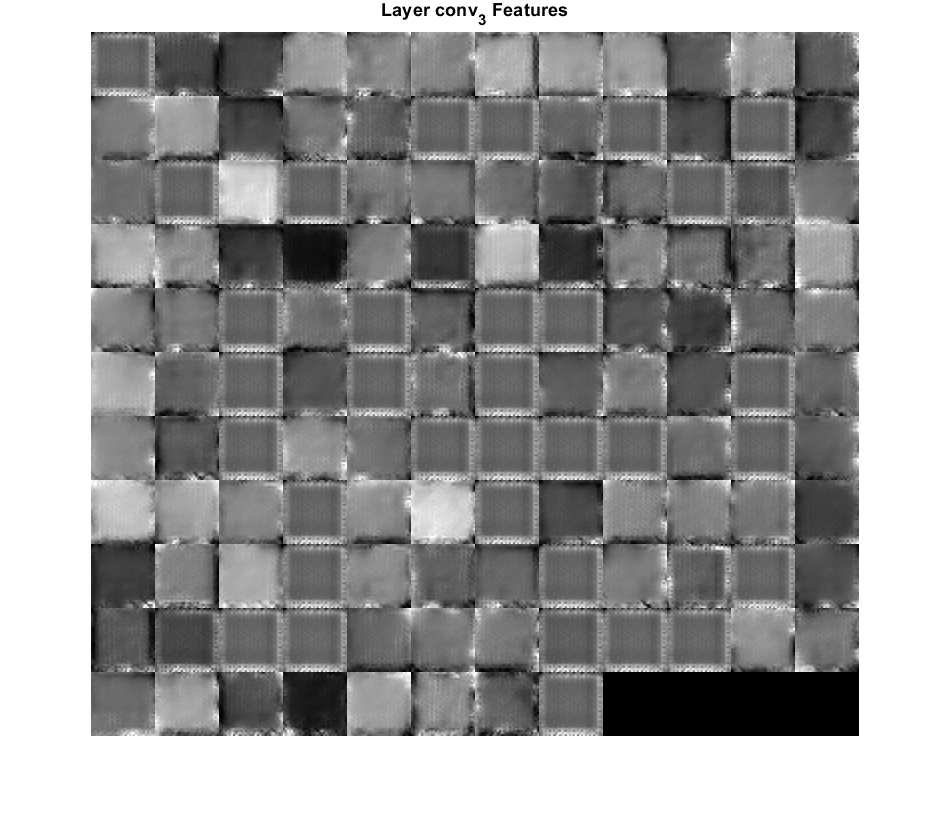

figure
I = imtile(I,'ThumbnailSize',[64 64]);
imshow(I)
title(['Layer ',name,' Features']);

[imdsTrain,imdsTest,imdsVal] = splitEachLabel(imds,0.7, 0.15, 0.15,'randomized');
test_results = char(classify(net.net,imdsTest));
count = 0;
TestLabels = char(imdsTest.Labels);
for i = 1:length(test_results)
    comp = strcmp(TestLabels(i,:), test_results(i,:));
    if (comp == 1)
        count = count + 1;
    end
end
test_accuracy = count/length(test_results)

test_accuracy = 0.6705